caseName = "DMD_combustorDataPressure";

load(caseName + "_ContTimeEigVals.mat");

whos

  Name                 Size                Bytes  Class     Attributes

  b                    1x4998              79968  double    complex   
  caseName             1x1                   198  string              
  contTimeEigVals      1x4999              79984  double    complex   
  initialState         1x38522            308176  double              




initialState = str2num(cell2mat(importdata(caseName + "_initialState",','))); % read data from file as charater array segmented by ',' put it into a matrix

b = str2num(cell2mat(importdata(caseName + "_initialAmplitudes",',')));


disp("ContTimeEigVals size: " + size(contTimeEigVals));

    "ContTimeEigVals size: 1"    "ContTimeEigVals size: 4999"



disp("initialState size: " + size(initialState));

    "initialState size: 1"    "initialState size: 38523"



disp("b size: " + size(b));

    "b size: 1"    "b size: 4999"




initialState = initialState(1:end-1); % resize to match length of contTimeEigVals
%b = b(1:end-1); % resize to match length of contTimeEigVals

## Visualization

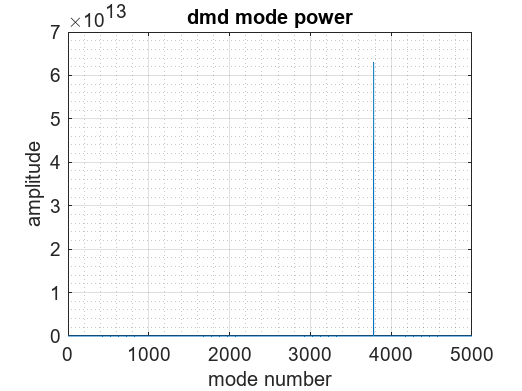

%mode power (scaled for grow/decay modes)
figure
plot(abs(b./contTimeEigVals));grid on; grid minor;
title("dmd mode power");
xlabel("mode number");
ylabel("amplitude");
savefig("figure"+caseName+"_dmdmodepower"+".fig"); 
saveas(gcf,"figure"+caseName+"_dmdmodepower"+".jpg");

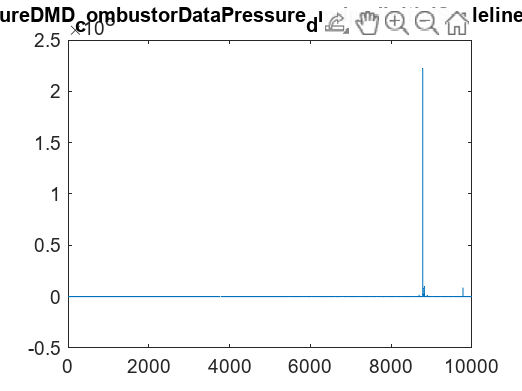


% Power Spectral Density

%not accounting for growth and decay modes.
figure
plot([log(abs(imag(contTimeEigVals/2/pi))),abs(b)])
title("figure"+caseName+"_dmdpsd"+"initialScale"+"lines"+".fig")
savefig("figure"+caseName+"_dmdpsd"+"initialScale"+"lines"+".fig");
saveas(gcf,"figure"+caseName+"_dmdpsd"+"initialScale"+"lines"+".jpg");

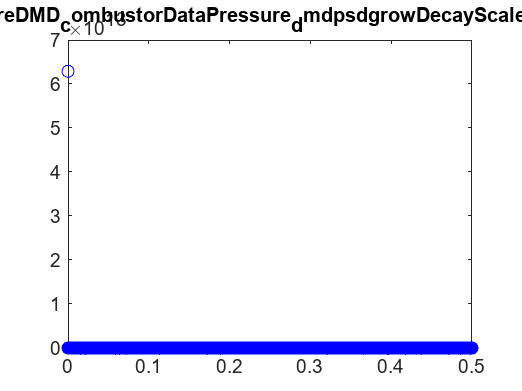


% Power Spectral Density scaled for growth and decay modes
figure
plot(abs(imag(contTimeEigVals/2/pi)),abs(b./contTimeEigVals),'bo') 
title("figure"+caseName+"_dmdpsd"+"growDecayScale"+"linear")
savefig("figure"+caseName+"_dmdpsd"+"growDecayScale"+"linear"+".fig");
saveas(gcf,"figure"+caseName+"_dmdpsd"+"growDecayScale"+"linear"+".jpg");

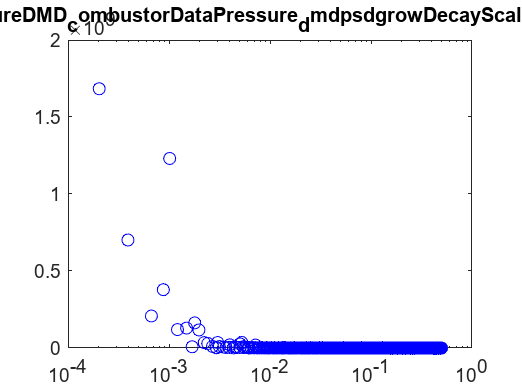


figure
semilogx(abs(imag(contTimeEigVals/2/pi)),abs(b./contTimeEigVals),'bo')
title("figure"+caseName+"_dmdpsd"+"growDecayScale"+"logx")
savefig("figure"+caseName+"_dmdpsd"+"growDecayScale"+"logx"+".fig");
saveas(gcf,"figure"+caseName+"_dmdpsd"+"growDecayScale"+"logx"+".jpg");

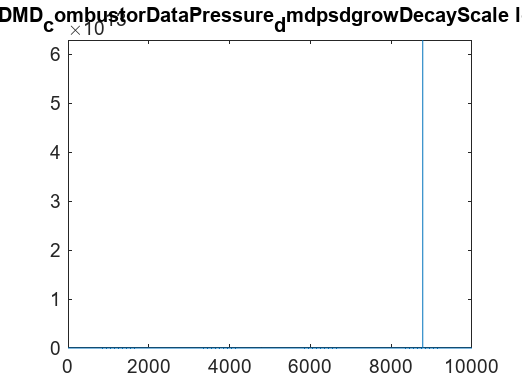


figure
plot([log(abs(imag(contTimeEigVals/2/pi))),abs(b./contTimeEigVals)]) %unsure if this is doing the correct thing 
title("figure"+caseName+"_dmdpsd"+"growDecayScale"+" log "+"lines")
savefig("figure"+caseName+"_dmdpsd"+"growDecayScale"+"lines"+".fig");
saveas(gcf,"figure"+caseName+"_dmdpsd"+"growDecayScale"+"lines"+".jpg");

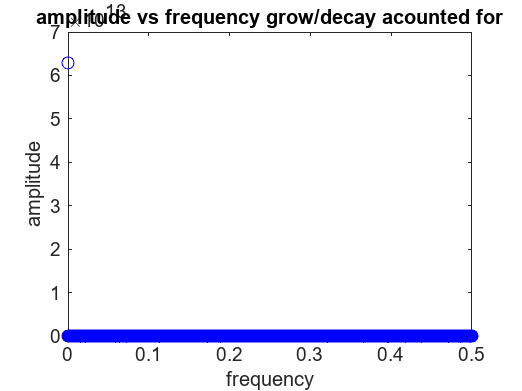


%these two are plotting the correct thing

%begin for debug
figure
plot((abs(imag(contTimeEigVals/2/pi))),abs(b./contTimeEigVals),'bo')
title("amplitude vs frequency grow/decay acounted for")
xlabel("frequency");
ylabel("amplitude");

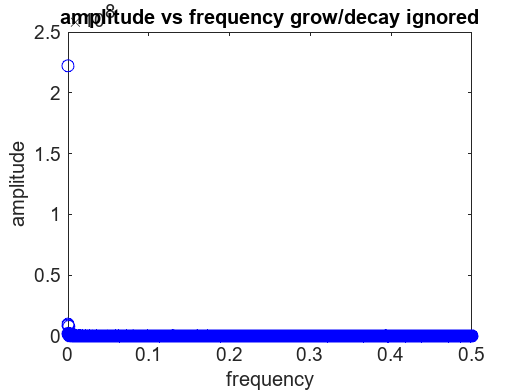


figure
plot((abs(imag(contTimeEigVals/2/pi))),abs(b),'bo')
title("amplitude vs frequency grow/decay ignored")
xlabel("frequency");
ylabel("amplitude");

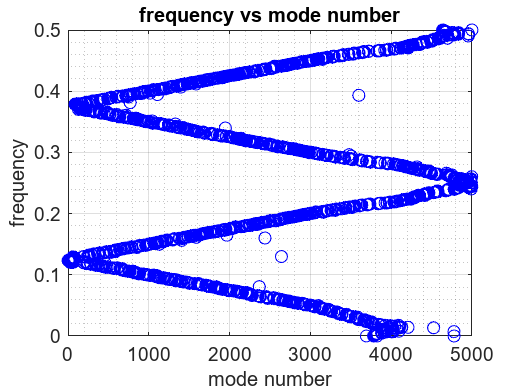

%end for debug


figure;
plot((abs(imag(contTimeEigVals/2/pi))),'bo'); grid on; grid minor;
title("frequency vs mode number");
ylabel("frequency");
xlabel("mode number");
savefig("figure"+caseName+" frequency vs mode number"+".fig");
saveas(gcf,"figure"+caseName+" frequency vs mode number"+".jpg");

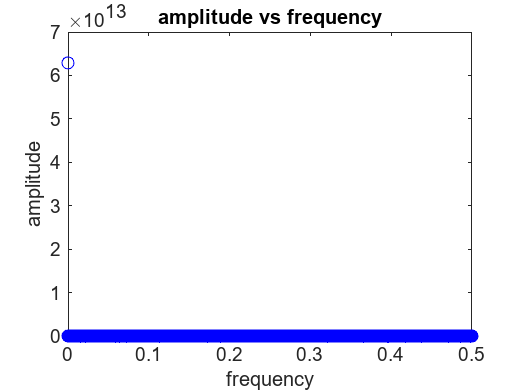



figure;plot((abs(imag(contTimeEigVals/2/pi))),abs(b./abs(contTimeEigVals)),'bo')
title("amplitude vs frequency")
ylabel("amplitude");
xlabel("frequency");
savefig("figure"+caseName+" amplitude vs frequency"+".fig");
saveas(gcf,"figure"+caseName+" amplitude vs frequency"+".jpg");

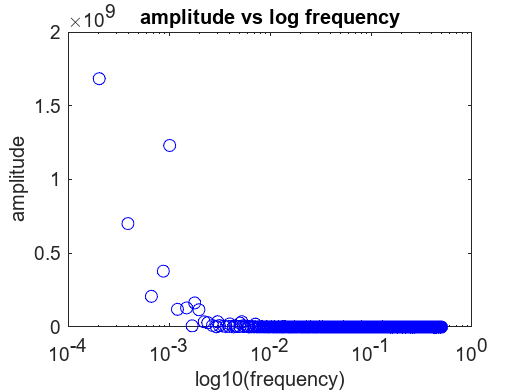


figure;semilogx((abs(imag(contTimeEigVals/2/pi))),abs(b./abs(contTimeEigVals)),'bo')
title("amplitude vs log frequency")
ylabel("amplitude");
xlabel("log10(frequency)");
savefig("figure"+caseName+" amplitude vs log frequency"+".fig");
saveas(gcf,"figure"+caseName+" amplitude vs log frequency"+".jpg");

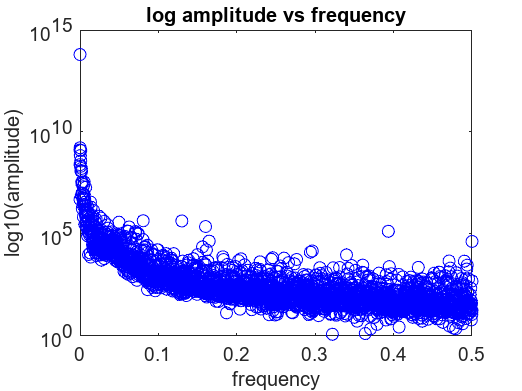


figure;semilogy((abs(imag(contTimeEigVals/2/pi))),abs(b./abs(contTimeEigVals)),'bo')
title("log amplitude vs frequency")
ylabel("log10(amplitude)");
xlabel("frequency");
savefig("figure"+caseName+" log amplitude vs frequency"+".fig");
saveas(gcf,"figure"+caseName+" log amplitude vs frequency"+".jpg");

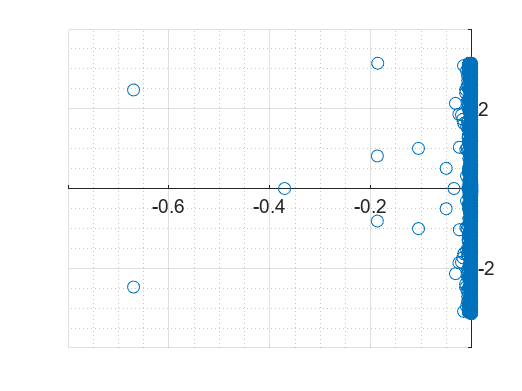

figure
scatter(real(contTimeEigVals),imag(contTimeEigVals));grid on; grid minor;
ax = gca;
ax.YAxisLocation = 'origin';
ax.XAxisLocation = 'origin';
savefig("figure"+caseName+"_dmdsectrum"+".fig");
saveas(gcf,"figure"+caseName+"_dmdsectrum"+".jpg");